# **Multi RBS analysis**

This script intend to vary the parameters of fractal coding to inspect the effect.

**This script include**

- effect of power 1's coefficient limitation

- effect of fix partittion vs adaptive partition

- effect of multi scale at vs fix scale

- apply to synth 8, 16k and 5 random 8, 16k speech 

**The metrices include**

- diff psnr

- diff spectrum visualization

- diff signal visualization

**The conclusion include**

- psnr trend for different coefficient limits

- psnr comparision of ADP vs FP

- psnr trend of fixed scales vs multi-rbs

## **Let start with synthesize signal**

warning off
%% parameters
RBS = [8 4 2];
Fs_inout = [1 1]; % Fs in/out ratio
coeffVal = [0.99, 1.2];
partitionType = [{'ADP_RBS2T8'}, {'FIXED_PARTITION_RBS'}];
numIndependVar = 3; % coefflimit, rbs, partition tpye
numDependVar = 2; % psnr of 8k, 16k signal
psnrMatrix = zeros((length(RBS) + 2)*length(coeffVal), numIndependVar + numDependVar);

%% read speech-paths
sigDir = 'F:\IFEFSR\SamplesSpeech\synth';
codeDir = 'F:\IFEFSR\SamplesSpeech\code';
filePathsLoc = 'F:\IFEFSR\SamplesSpeech\synth_ids8.txt';
fid = fopen(filePathsLoc,'r');
allFilePaths = textscan(fid, '%s','Delimiter','\n');
allFilePaths = allFilePaths{1};
fclose(fid);

%% for each sampling rate
for fsIdx = 1:2
    FsShort = 8*fsIdx;
    
    %% for each coefficient limits
    for coeffIdx = 1:2
        for idx = 1:1
            %% Read original sig for baseline
            inSigPath = normpath([sigDir '\' num2str(FsShort) ...
                '\' allFilePaths{idx}]);
            sig = rawread(inSigPath);
            
            % plot original sig
            caption = ['Original signal Fs = ' num2str(FsShort) 'k'];
            plotSigVsFreqRes( sig, caption, FsShort*1000 );
            
            %% read code from dataset
            % no need to use matlab
            F = cell(size(RBS)); % compose multi-rbs fractal code
            for rbsIdx = 1:3 %length(RBS)
                
                % load the code and decompress it
                inCodePath = normpath([ codeDir '\SUBSYNTH' num2str(FsShort) ...
                    '_FIXED_PARTITION_RBS' num2str(RBS(rbsIdx)) '_LC' ...
                    sprintf('%03d', coeffVal(coeffIdx) * 100) ...
                    '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
                dat = load(inCodePath);
                F(rbsIdx) = {dat.f};
                recSig = decompressAudioFC(dat.f, Fs_inout(1), Fs_inout(2), 15);
                
                % plot the reconstruc signal
                caption = ['Fixed FC R scale at ' num2str(RBS(rbsIdx)) ' Fs = ' num2str(FsShort) 'k' ...
                    ' LC ' num2str(coeffVal(coeffIdx)) ...
                    ' psnr = ' num2str(PSNR(sig, recSig))];
                plotSigVsFreqRes( recSig, caption, FsShort*1000 );
                
                % collect psnr matrix for later evaluate
                psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, 1) = coeffVal(coeffIdx);
                psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, 2) = RBS(rbsIdx);
                psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, 3) = 0; % fixed partition
                psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, numIndependVar + fsIdx) ...
                    = PSNR(sig, recSig);
            end
            
            %% Multi R coding section
            recSig = MultiScaleAFCDecoder(F, Fs_inout(1), Fs_inout(2), 15);
            caption = ['Multi R scales FC' ' Fs = ' num2str(FsShort)  ...
                'k psnr = ' num2str(PSNR(sig, recSig))];
            plotSigVsFreqRes( recSig, caption, FsShort*1000 );
            
            % collect psnr matrix for later evaluate
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 1, 1) = coeffVal(coeffIdx);
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 1, 2) = 0;
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 1, 3) = 0; % composite fixed partition
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 1, numIndependVar + fsIdx) ...
                = PSNR(sig, recSig);
            
            %% adaptive partition coding section
            nCodePath = normpath([ codeDir '\SUBSYNTH' num2str(FsShort) ...
                '_ADP_RBS2T8_LC' ...
                sprintf('%03d', coeffVal(coeffIdx) * 100) ...
                '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
            dat = load(inCodePath);
            recSig = decompressAudioFC(dat.f, Fs_inout(1), Fs_inout(2), 15);
            caption = ['ADP2T8 FC' ' Fs = ' num2str(FsShort)  ...
                'k psnr = ' num2str(PSNR(sig, recSig))];
            plotSigVsFreqRes( recSig, caption, FsShort*1000 );
            
            % collect psnr matrix for later evaluate
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 2, 1) = coeffVal(coeffIdx);
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 2, 2) = 0;
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 2, 3) = 1; % adaptive partition
            psnrMatrix((coeffIdx - 1)*(length(RBS) + 2) + 2, numIndependVar + fsIdx) ...
                = PSNR(sig, recSig);
            
        end
    end
end


**First experiment is effect of **`coeff limit`** on synth signals**

At finest scale, the rbs-2 is the best but depend on coeff limit.

The smaller rbs archieved higher psnr if limit coeff by 0.99

The smaller rbs archieved higher psnr except rbs-2 if limit coeff by 1.2

**Second experiment is analysis effect of fixed partition vs adaptive partition**

## Third experiment is analysis effect of fixed vs multi range scales

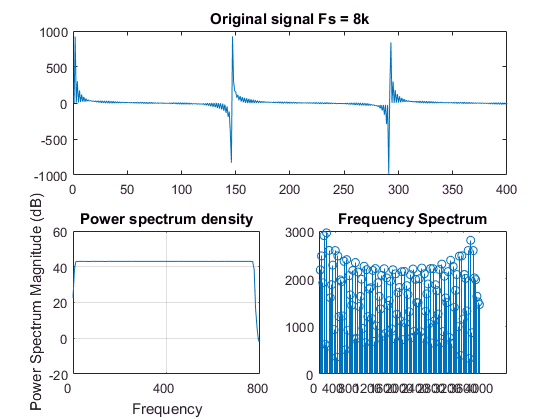

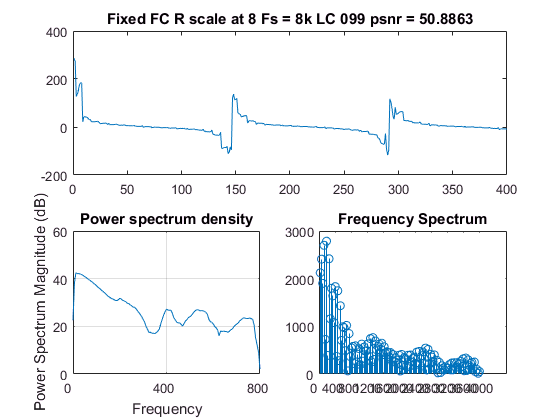

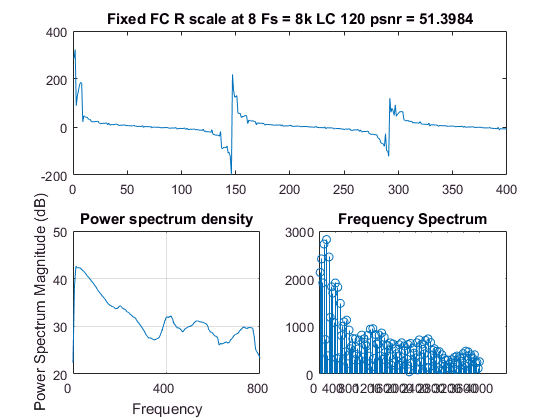

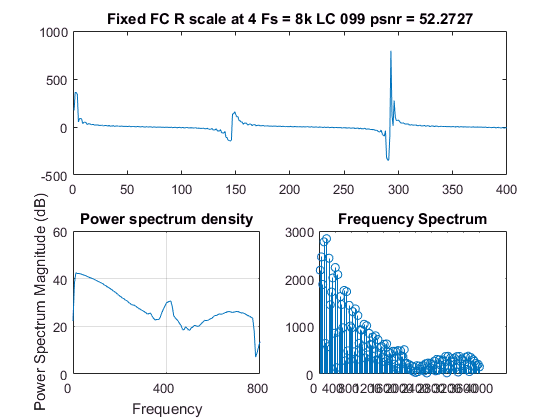

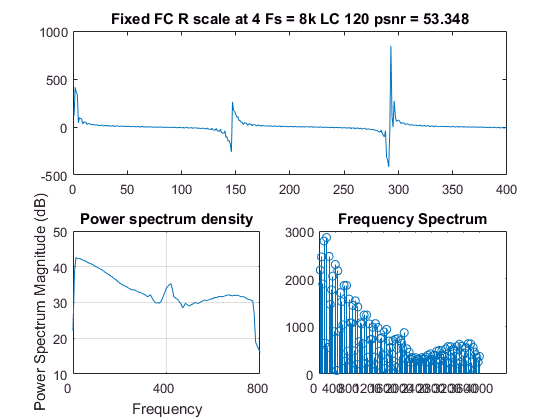

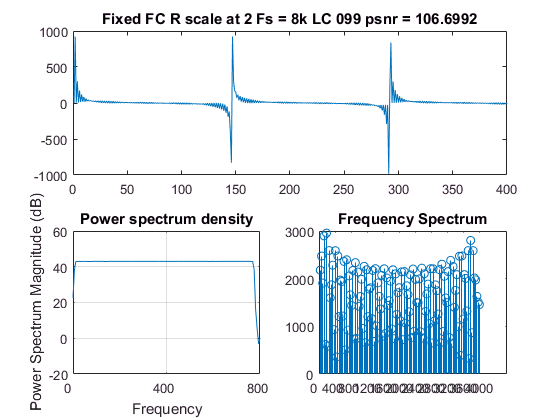

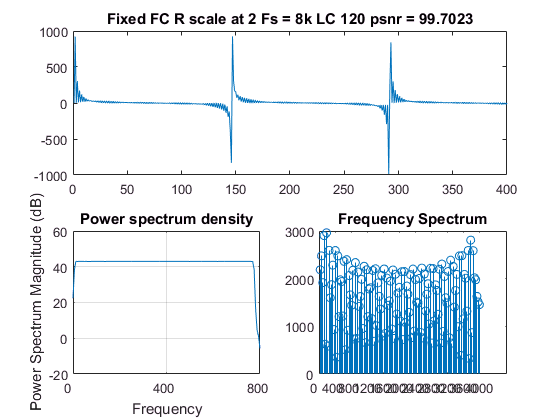

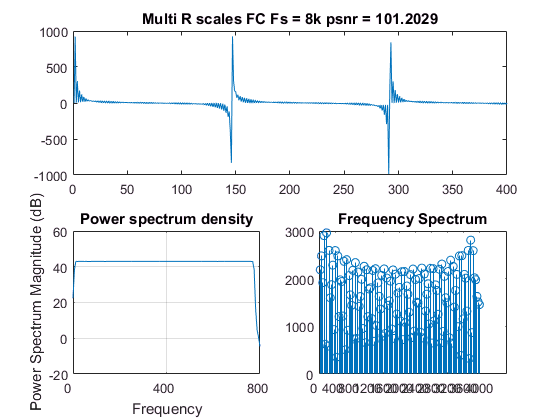

Next, sub-corpus speeches are evaluated 

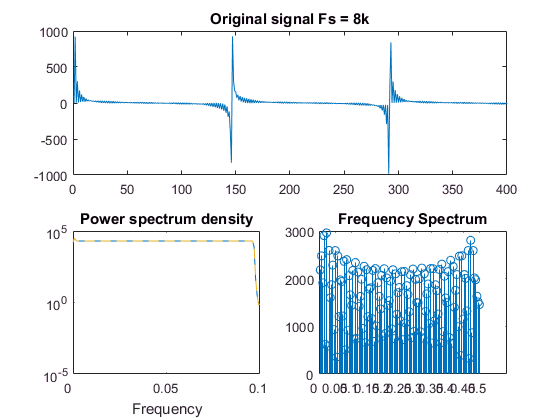

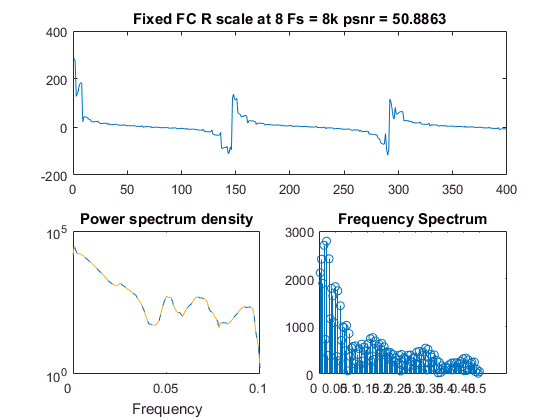

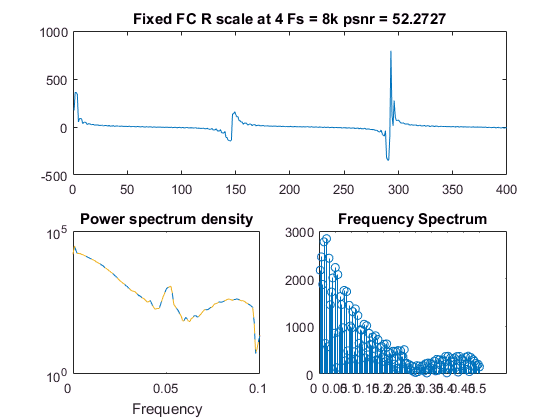

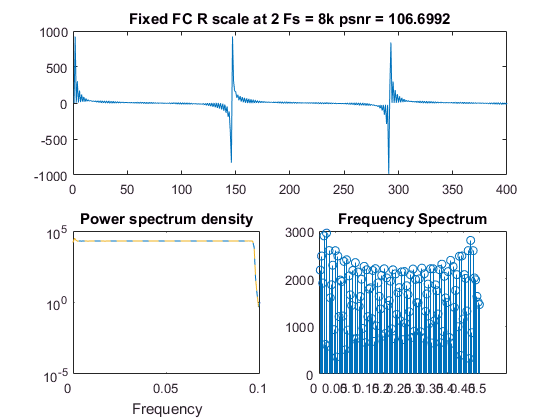

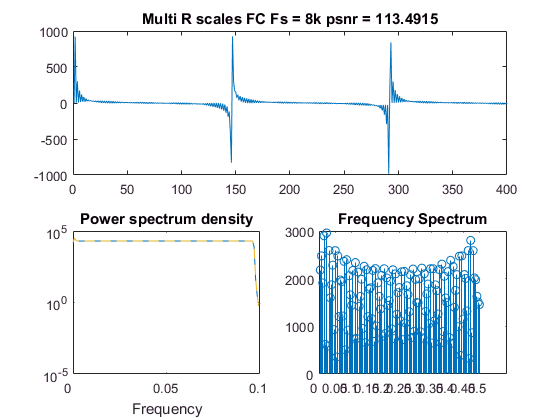

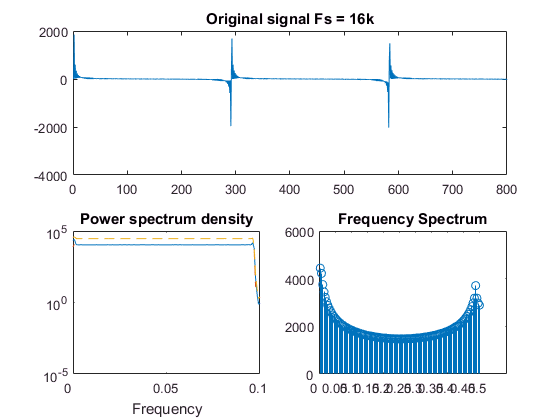

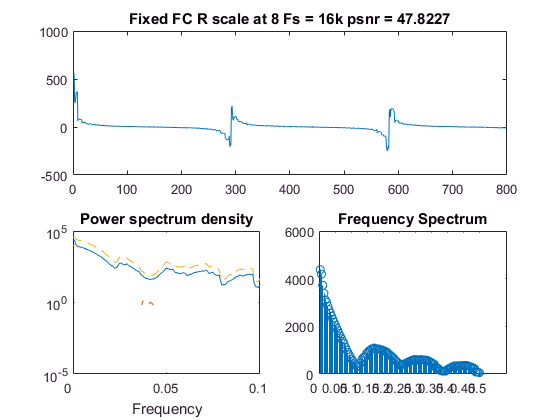

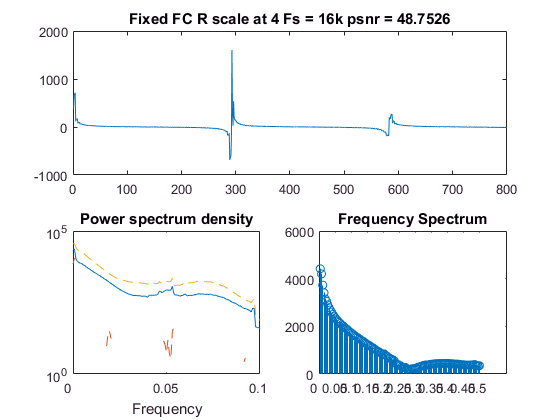

warning off

Error using load
Unable to read file 'F:/IFEFSR/SamplesSpeech/code/SUBAN48_FIXED_PARTITION_RBS8_LC099/an4_clstk/msct/cen2-msct-b.mat'. No such file or directory.


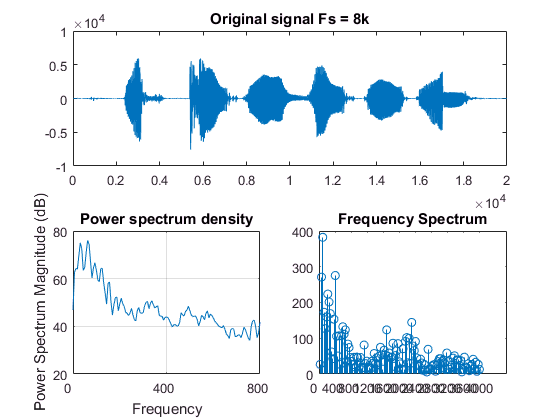

%% parameters
RBS = [8 4 2];
Fs_inout = [1 1]; % Fs in/out ratio
coeffVal = [0.99, 1.2];
partitionType = [{'ADP_RBS2T8'}, {'FIXED_PARTITION_RBS'}];
numIndependVar = 3; % coefflimit, rbs, partition tpye
numDependVar = 2; % psnr of 8k, 16k signal
psnrMatrix_2 = zeros((length(RBS) + 2)*length(coeffVal), numIndependVar + numDependVar);

%% read speech-paths
sigDir = 'F:\IFEFSR\SamplesSpeech\speech';
codeDir = 'F:\IFEFSR\SamplesSpeech\code';
filePathsLoc = 'F:\IFEFSR\SamplesSpeech\ids8.txt';
fid = fopen(filePathsLoc,'r');
allFilePaths = textscan(fid, '%s','Delimiter','\n');
allFilePaths = allFilePaths{1};
fclose(fid);

%% for each sampling rate
for fsIdx = 1:2
    FsShort = 8*fsIdx;
    
    %% for each coefficient limits
    for coeffIdx = 1:2
        for idx = 1:length(allFilePaths)
            %% Read original sig for baseline
            inSigPath = normpath([sigDir '\' num2str(FsShort) ...
                '\' allFilePaths{idx}]);
            sig = rawread(inSigPath);
            
            % plot original sig
            caption = ['Original signal Fs = ' num2str(FsShort) 'k'];
            plotSigVsFreqRes( sig, caption, FsShort*1000 );
            
            %% read code from dataset
            % no need to use matlab
            F = cell(size(RBS)); % compose multi-rbs fractal code
            for rbsIdx = 1:3 %length(RBS)
                
                % load the code and decompress it
                inCodePath = normpath([ codeDir '\SUBAN4' num2str(FsShort) ...
                    '_FIXED_PARTITION_RBS' num2str(RBS(rbsIdx)) '_COEFF' ...
                    sprintf('%03d', coeffVal(coeffIdx) * 100) ...
                    '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
                dat = load(inCodePath);
                F(rbsIdx) = {dat.f};
                recSig = decompressAudioFC(dat.f, Fs_inout(1), Fs_inout(2), 15);
                
                % plot the reconstruc signal
                caption = ['Fixed FC R scale at ' num2str(RBS(rbsIdx)) ' Fs = ' num2str(FsShort) 'k' ...
                    ' LC ' num2str(coeffVal(coeffIdx)) ...
                    ' psnr = ' num2str(PSNR(sig, recSig))];
                plotSigVsFreqRes( recSig, caption, FsShort*1000 );
                
                % collect psnr matrix for later evaluate
                psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, 1) = coeffVal(coeffIdx);
                psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, 2) = RBS(rbsIdx);
                psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, 3) = 0; % fixed partition
                psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + rbsIdx, numIndependVar + ((idx-1)*2)+ fsIdx) ...
                    = PSNR(sig, recSig);
            end
            
            %% Multi R coding section
            recSig = MultiScaleAFCDecoder(F, Fs_inout(1), Fs_inout(2), 15);
            caption = ['Multi R scales FC' ' Fs = ' num2str(FsShort)  ...
                'k psnr = ' num2str(PSNR(sig, recSig))];
            plotSigVsFreqRes( recSig, caption, FsShort*1000 );
            
            % collect psnr matrix for later evaluate
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 1, 1) = coeffVal(coeffIdx);
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 1, 2) = 0;
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 1, 3) = 0; % composite fixed partition
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 1, numIndependVar + ((idx-1)*2) + fsIdx) ...
                = PSNR(sig, recSig);
            
            %% adaptive partition coding section
            nCodePath = normpath([ codeDir '\SUBAN4' num2str(FsShort) ...
                '_ADP_RBS2T8_COEFF' ...
                sprintf('%03d', coeffVal(coeffIdx) * 100) ...
                '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
            dat = load(inCodePath);
            recSig = decompressAudioFC(dat.f, Fs_inout(1), Fs_inout(2), 15);
            caption = ['ADP2T8 FC' ' Fs = ' num2str(FsShort)  ...
                'k psnr = ' num2str(PSNR(sig, recSig))];
            plotSigVsFreqRes( recSig, caption, FsShort*1000 );
            
            % collect psnr matrix for later evaluate
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 2, 1) = coeffVal(coeffIdx);
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 2, 2) = 0;
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 2, 3) = 1; % adaptive partition
            psnrMatrix_2((coeffIdx - 1)*(length(RBS) + 2) + 2, numIndependVar + fsIdx) ...
                = PSNR(sig, recSig);
            
        end
    end
end